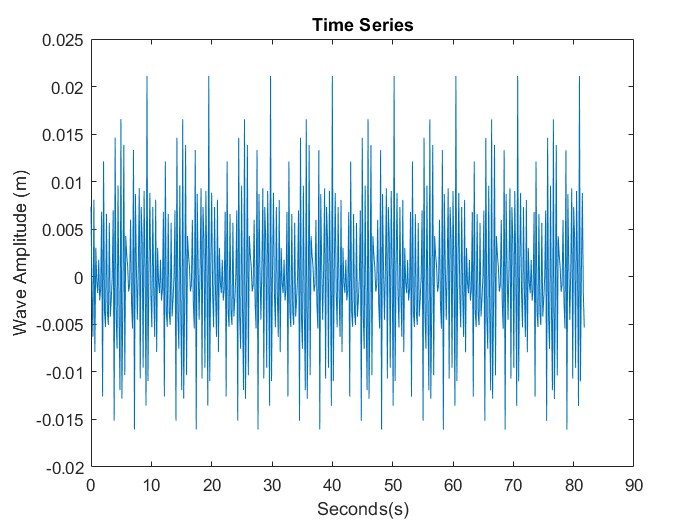

Textfile = load("timeSeries");
writematrix(Textfile, "PSD.csv");
timeSeriesData = readtable("PSD.csv");


N =  1024 - 1; 
timeSeriesData = detrend(timeSeriesData{:, 1}/(8192))*9.81; %data is symmetric, *2 to account for contribution of other half
fs = 6.25;
time = 1/fs*(0:(N));

plot(time(1:512), timeSeriesData(1:512)); %only plotting the real side of the dataset 
title("Time Series");
xlabel("Seconds(s)");
ylabel("Wave Amplitude (m)");